%Get number of cases run and cases run in each batch
numeach = zeros(200, 1);
for j = 1:200
    partitionno = j;
    if exist(sprintf('ImpData/progress%d.mat', partitionno), "file")
        numsims = load(sprintf('ImpData/progress%d.mat', partitionno)).i;
    else
        continue
    end
    numeach(partitionno) = numsims;


end
sum(numeach) 

ans = 1132000

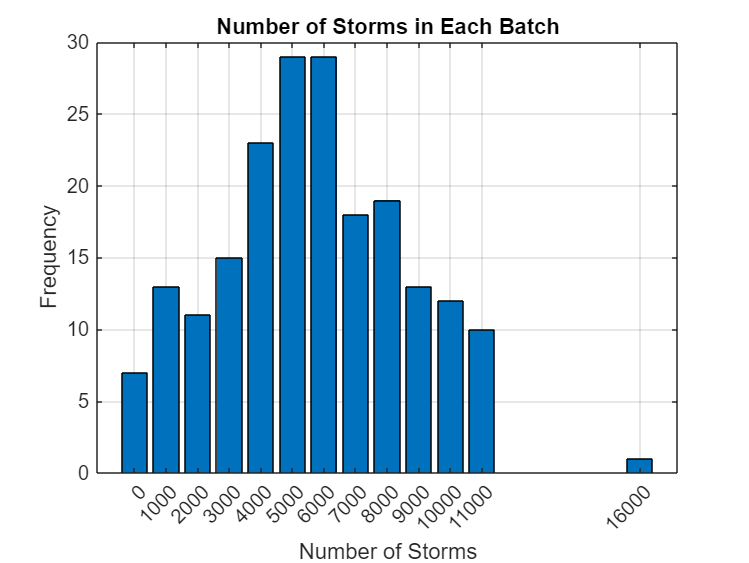

[unique_vals, ~, idx] = unique(numeach);
counts = accumarray(idx, 1);
bar(unique_vals, counts);
xlabel('Number of Storms');
ylabel('Frequency');
title('Number of Storms in Each Batch');
grid on;

%get batches which were unable to complete 1000 storms
zero_indices = find(numeach == 0);
disp(zero_indices);

    59
    66
    73
    77
   125
   161
   183



for i = 1:1000
    a = b{i};
    numm = size(a.busesremoved, 1) + size(a.tlremoved, 2);
    if numm > 30
        disp(size(a.busesremoved, 1) + size(a.tlremoved, 2))
    end
end

    72



%get number of lines and buses per case
numlines = zeros(sum(numeach) , 1);
numbuses = zeros(sum(numeach) , 1);
%make it total, lines, buses removed
i = 1;
for j = 1:200
    partitionno = j;
    if exist(sprintf('ImpData/progress%d.mat', partitionno), "file")
        data = load(sprintf('ImpData/outputstruct%d.mat', partitionno)).fulloutputstruct;
    else
        continue
    end
    for k = 1:numeach(j) %numeach(j) holds the number of sims per partition
        numlines(i) = size(data(k).caseremlineimportances, 1);
        numbuses(i) = size(data(k).caserembusimportances, 1);
        i = i+1;
        if mod(i, 2000) == 0
            i
        end
    end    
end

i = 2000

i = 4000

i = 6000

i = 8000

i = 10000

i = 12000

i = 14000

i = 16000

i = 18000

i = 20000

i = 22000

i = 24000

i = 26000

i = 28000

i = 30000

i = 32000

i = 34000

i = 36000

i = 38000

i = 40000

i = 42000

i = 44000

i = 46000

i = 48000

i = 50000

i = 52000

i = 54000

i = 56000

i = 58000

i = 60000

i = 62000

i = 64000

i = 66000

i = 68000

i = 70000

i = 72000

i = 74000

i = 76000

i = 78000

i = 80000

i = 82000

i = 84000

i = 86000

i = 88000

i = 90000

i = 92000

i = 94000

i = 96000

i = 98000

i = 100000

i = 102000

i = 104000

i = 106000

i = 108000

i = 110000

i = 112000

i = 114000

i = 116000

i = 118000

i = 120000

i = 122000

i = 124000

i = 126000

i = 128000

i = 130000

i = 132000

i = 134000

i = 136000

i = 138000

i = 140000

i = 142000

i = 144000

i = 146000

i = 148000

i = 150000

i = 152000

i = 154000

i = 156000

i = 158000

i = 160000

i = 162000

i = 164000

i = 166000

i = 168000

i = 170000

i = 172000

i = 174000

i = 176000

i = 178000

i = 180000

i = 182000

i = 184000

i = 186000

i = 188000

i = 190000

i = 192000

i = 194000

i = 196000

i = 198000

i = 200000

i = 202000

i = 204000

i = 206000

i = 208000

i = 210000

i = 212000

i = 214000

i = 216000

i = 218000

i = 220000

i = 222000

i = 224000

i = 226000

i = 228000

i = 230000

i = 232000

i = 234000

i = 236000

i = 238000

i = 240000

i = 242000

i = 244000

i = 246000

i = 248000

i = 250000

i = 252000

i = 254000

i = 256000

i = 258000

i = 260000

i = 262000

i = 264000

i = 266000

i = 268000

i = 270000

i = 272000

i = 274000

i = 276000

i = 278000

i = 280000

i = 282000

i = 284000

i = 286000

i = 288000

i = 290000

i = 292000

i = 294000

i = 296000

i = 298000

i = 300000

i = 302000

i = 304000

i = 306000

i = 308000

i = 310000

i = 312000

i = 314000

i = 316000

i = 318000

i = 320000

i = 322000

i = 324000

i = 326000

i = 328000

i = 330000

i = 332000

i = 334000

i = 336000

i = 338000

i = 340000

i = 342000

i = 344000

i = 346000

i = 348000

i = 350000

i = 352000

i = 354000

i = 356000

i = 358000

i = 360000

i = 362000

i = 364000

i = 366000

i = 368000

i = 370000

i = 372000

i = 374000

i = 376000

i = 378000

i = 380000

i = 382000

i = 384000

i = 386000

i = 388000

i = 390000

i = 392000

i = 394000

i = 396000

i = 398000

i = 400000

i = 402000

i = 404000

i = 406000

i = 408000

i = 410000

i = 412000

i = 414000

i = 416000

i = 418000

i = 420000

i = 422000

i = 424000

i = 426000

i = 428000

i = 430000

i = 432000

i = 434000

i = 436000

i = 438000

i = 440000

i = 442000

i = 444000

i = 446000

i = 448000

i = 450000

i = 452000

i = 454000

i = 456000

i = 458000

i = 460000

i = 462000

i = 464000

i = 466000

i = 468000

i = 470000

i = 472000

i = 474000

i = 476000

i = 478000

i = 480000

i = 482000

i = 484000

i = 486000

i = 488000

i = 490000

i = 492000

i = 494000

i = 496000

i = 498000

i = 500000

i = 502000

i = 504000

i = 506000

i = 508000

i = 510000

i = 512000

i = 514000

i = 516000

i = 518000

i = 520000

i = 522000

i = 524000

i = 526000

i = 528000

i = 530000

i = 532000

i = 534000

i = 536000

i = 538000

i = 540000

i = 542000

i = 544000

i = 546000

i = 548000

i = 550000

i = 552000

i = 554000

i = 556000

i = 558000

i = 560000

i = 562000

i = 564000

i = 566000

i = 568000

i = 570000

i = 572000

i = 574000

i = 576000

i = 578000

i = 580000

i = 582000

i = 584000

i = 586000

i = 588000

i = 590000

i = 592000

i = 594000

i = 596000

i = 598000

i = 600000

i = 602000

i = 604000

i = 606000

i = 608000

i = 610000

i = 612000

i = 614000

i = 616000

i = 618000

i = 620000

i = 622000

i = 624000

i = 626000

i = 628000

i = 630000

i = 632000

i = 634000

i = 636000

i = 638000

i = 640000

i = 642000

i = 644000

i = 646000

i = 648000

i = 650000

i = 652000

i = 654000

i = 656000

i = 658000

i = 660000

i = 662000

i = 664000

i = 666000

i = 668000

i = 670000

i = 672000

i = 674000

i = 676000

i = 678000

i = 680000

i = 682000

i = 684000

i = 686000

i = 688000

i = 690000

i = 692000

i = 694000

i = 696000

i = 698000

i = 700000

i = 702000

i = 704000

i = 706000

i = 708000

i = 710000

i = 712000

i = 714000

i = 716000

i = 718000

i = 720000

i = 722000

i = 724000

i = 726000

i = 728000

i = 730000

i = 732000

i = 734000

i = 736000

i = 738000

i = 740000

i = 742000

i = 744000

i = 746000

i = 748000

i = 750000

i = 752000

i = 754000

i = 756000

i = 758000

i = 760000

i = 762000

i = 764000

i = 766000

i = 768000

i = 770000

i = 772000

i = 774000

i = 776000

i = 778000

i = 780000

i = 782000

i = 784000

i = 786000

i = 788000

i = 790000

i = 792000

i = 794000

i = 796000

i = 798000

i = 800000

i = 802000

i = 804000

i = 806000

i = 808000

i = 810000

i = 812000

i = 814000

i = 816000

i = 818000

i = 820000

i = 822000

i = 824000

i = 826000

i = 828000

i = 830000

i = 832000

i = 834000

i = 836000

i = 838000

i = 840000

i = 842000

i = 844000

i = 846000

i = 848000

i = 850000

i = 852000

i = 854000

i = 856000

i = 858000

i = 860000

i = 862000

i = 864000

i = 866000

i = 868000

i = 870000

i = 872000

i = 874000

i = 876000

i = 878000

i = 880000

i = 882000

i = 884000

i = 886000

i = 888000

i = 890000

i = 892000

i = 894000

i = 896000

i = 898000

i = 900000

i = 902000

i = 904000

i = 906000

i = 908000

i = 910000

i = 912000

i = 914000

i = 916000

i = 918000

i = 920000

i = 922000

i = 924000

i = 926000

i = 928000

i = 930000

i = 932000

i = 934000

i = 936000

i = 938000

i = 940000

i = 942000

i = 944000

i = 946000

i = 948000

i = 950000

i = 952000

i = 954000

i = 956000

i = 958000

i = 960000

i = 962000

i = 964000

i = 966000

i = 968000

i = 970000

i = 972000

i = 974000

i = 976000

i = 978000

i = 980000

i = 982000

i = 984000

i = 986000

i = 988000

i = 990000

i = 992000

i = 994000

i = 996000

i = 998000

i = 1000000

i = 1002000

i = 1004000

i = 1006000

i = 1008000

i = 1010000

i = 1012000

i = 1014000

i = 1016000

i = 1018000

i = 1020000

i = 1022000

i = 1024000

i = 1026000

i = 1028000

i = 1030000

i = 1032000

i = 1034000

i = 1036000

i = 1038000

i = 1040000

i = 1042000

i = 1044000

i = 1046000

i = 1048000

i = 1050000

i = 1052000

i = 1054000

i = 1056000

i = 1058000

i = 1060000

i = 1062000

i = 1064000

i = 1066000

i = 1068000

i = 1070000

i = 1072000

i = 1074000

i = 1076000

i = 1078000

i = 1080000

i = 1082000

i = 1084000

i = 1086000

i = 1088000

i = 1090000

i = 1092000

i = 1094000

i = 1096000

i = 1098000

i = 1100000

i = 1102000

i = 1104000

i = 1106000

i = 1108000

i = 1110000

i = 1112000

i = 1114000

i = 1116000

i = 1118000

i = 1120000

i = 1122000

i = 1124000

i = 1126000

i = 1128000

i = 1130000

i = 1132000

%store the above because it takes forever and I don't want data loss
save('numlinesineachcaseapr5.mat', 'numlines')
save('numbusesineachcaseapr5.mat', 'numbuses')

%%use stuff above to generate a count of the number of cases where each
%%number of assets were removed
[unique_valslines, ~, idxlines] = unique(numlines);
countslines = accumarray(idxlines, 1);


[unique_valsbuses, ~, idxbuses] = unique(numbuses);
countsbuses = accumarray(idxbuses, 1);

%get a graph of the distribution of the number of assets removed in each case
numassets = numlines + numbuses;
nnz(numassets)

ans = 179146

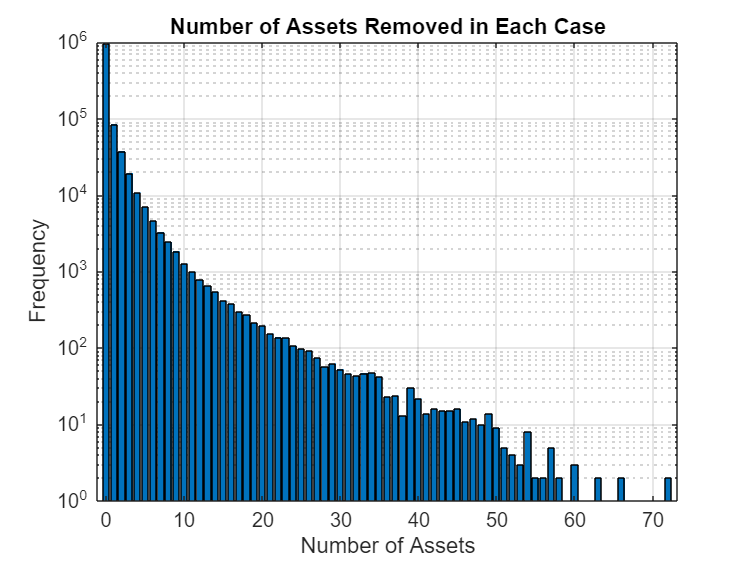

[unique_valsassets, ~, idxassets] = unique(numassets);
countsassets = accumarray(idxassets, 1);
bar(unique_valsassets, countsassets);
xlabel('Number of Assets');
ylabel('Frequency');
title('Number of Assets Removed in Each Case');
set(gca, 'YScale', 'log')
grid on;

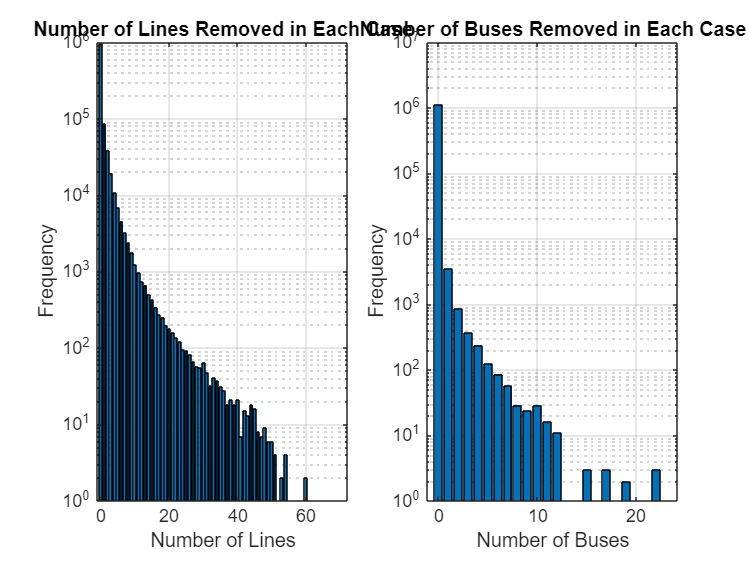

%get a graph of the distribution of the number of lines and buses removed in each case
subplot(1,2,1); % 1 row, 2 columns, first subplot
bar(unique_valslines, countslines);
title('Number of Lines Removed in Each Case');
xlabel('Number of Lines');
ylabel('Frequency');
set(gca, 'YScale', 'log')
grid on;

% Second subplot
subplot(1,2,2); % 1 row, 2 columns, second subplot
bar(unique_valsbuses, countsbuses);
title('Number of Buses Removed in Each Case');
xlabel('Number of Buses');
ylabel('Frequency');
set(gca, 'YScale', 'log')
grid on;

%get total bus importance table 
totalbusimportanceData = table([], [], [], 'VariableNames', {'bus', 'importance', 'hits'});

for i = 1:200
    partitionno = i;
    if exist(sprintf('ImpData/busimp%d.mat', partitionno), "file")
        simbusimportances = load(sprintf('ImpData/busimp%d.mat', partitionno)).totalbusimportanceData;
    else
        continue
    end
    for j = 1:size(simbusimportances, 1)
        if ~isempty(totalbusimportanceData.bus)
            [isInTable, rowIdx] = ismember(simbusimportances.bus(j), totalbusimportanceData.bus); % Check if index is in the table
        else
            isInTable = false;
        end
    
        if isInTable
            % Update the value
            totalbusimportanceData.importance(rowIdx) = totalbusimportanceData.importance(rowIdx) + simbusimportances.importance(j);
            totalbusimportanceData.hits(rowIdx) = totalbusimportanceData.hits(rowIdx) + 1;
        else
            % Append a new row
            newRow = {simbusimportances.bus(j), simbusimportances.importance(j), 1};
            totalbusimportanceData = [totalbusimportanceData; newRow];
        end
    end
    if mod(i, 40) == 0
        disp(i)
    end
end

    40

    80

   120

   160

   200



%get total line importance table
totallineimportanceMap = containers.Map('KeyType', 'char', 'ValueType', 'any');

for i = 1:200
    partitionno = i;
    fileName = sprintf('ImpData/lineimp%d.mat', partitionno);
    if exist(fileName, "file")
        simlineimportances = load(fileName).totallineimportanceData;
    else
        continue
    end

    for j = 1:size(simlineimportances, 1)
        % Create a unique key for fast lookup
        key = sprintf('%d-%d-%d', simlineimportances.line(j).busfrom, ...
                                   simlineimportances.line(j).busto, ...
                                   simlineimportances.line(j).connumber);
        if isKey(totallineimportanceMap, key)
            % Update existing entry
            entry = totallineimportanceMap(key);
            entry.importance = entry.importance + simlineimportances.importance(j);
            entry.hits = entry.hits + 1;
            totallineimportanceMap(key) = entry;
        else
            % Add new entry
            totallineimportanceMap(key) = struct( ...
                'line', simlineimportances.line(j), ...
                'importance', simlineimportances.importance(j), ...
                'hits', 1);
        end
    end

    if mod(i, 40) == 0
        disp(i)
    end
end

    40

    80

   120

   160

   200




% Convert the map to a table
keys = totallineimportanceMap.keys;
numEntries = length(keys);
lineArr = cell(numEntries, 1);
importanceArr = zeros(numEntries, 1);
hitsArr = zeros(numEntries, 1);

for i = 1:numEntries
    entry = totallineimportanceMap(keys{i});
    lineArr{i} = entry.line;
    importanceArr(i) = entry.importance;
    hitsArr(i) = entry.hits;
end

totallineimportanceData = table(lineArr, importanceArr, hitsArr, ...
    'VariableNames', {'line', 'importance', 'hits'});


%get the distribution of the number of times each bus and line is hit by a tornado
mpc = loadcase("Texas7k_20210804.m");
numbuses = size(mpc.bus, 1)

numbuses = 6717

numbranches = size(mpc.branch, 1)

numbranches = 9140

hitslinedata = totallineimportanceData.hits;
hitsbusdata = totalbusimportanceData.hits;

[unique_vals_hitslines, ~, idxhitslines] = unique(hitslinedata);
counts_hitlines = accumarray(idxhitslines, 1);

[unique_vals_hitsbuses, ~, idxhitsbuses] = unique(hitsbusdata);
counts_hitbuses = accumarray(idxhitsbuses, 1);

%unique_vals_hitslines = [0; unique_vals_hitslines]

unique_vals_hitsbuses = [0; unique_vals_hitsbuses]

unique_vals_hitsbuses =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



%counts_hitlines = [numbranches - size(hitslinedata, 1); counts_hitlines];
counts_hitbuses = [numbuses - size(hitsbusdata, 1); counts_hitbuses];
zero_linesremoved = numbranches - size(hitslinedata, 1)

zero_linesremoved = 2070

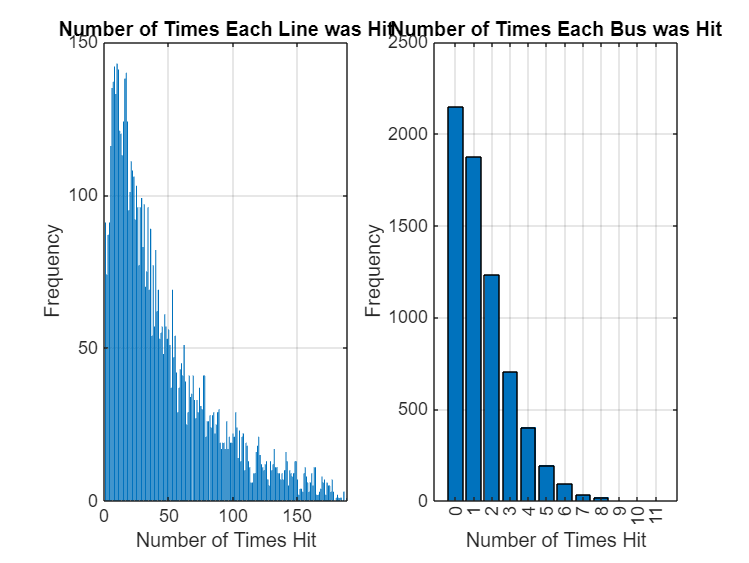



subplot(1,2,1); % 1 row, 2 columns, first subplot
bar(unique_vals_hitslines, counts_hitlines);
title('Number of Times Each Line was Hit');
xlabel('Number of Times Hit');
ylabel('Frequency');
%set(gca, 'YScale', 'log')
grid on;

% Second subplot
subplot(1,2,2); % 1 row, 2 columns, second subplot
bar(unique_vals_hitsbuses, counts_hitbuses);
title('Number of Times Each Bus was Hit');
xlabel('Number of Times Hit');
ylabel('Frequency');
%set(gca, 'YScale', 'log')
grid on;